# One Dimensional Eikonal using 5th WENO Fast Sweep Algorithm

After suffering from one more failure to make the 5th order WENO Algorithm for Two Eikonal Equation, i am moving on solve for the same problem with same algorithm, but with reduced dimension. The problem definition is given below:

## 1.Problem Definition

So for simplicity, I will be taking the same problem as I have tajen in my previous problem.

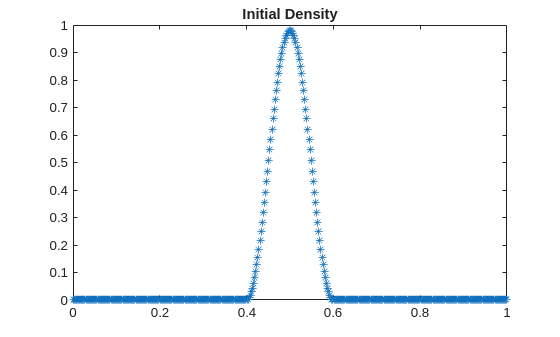

%-----Parameters----%

N = 400;                % Grid Points
L = 1;                  % Lenght
dx = N/L;               % Grid Space
x = linspace(0,L,N);    % Domian

%-----Density Definition------%

rho_gauss = zeros(size(x));

for i = 1:1:N
     if x(i) >= 0.4 && x(i) <= 0.6
     % Raised cosine bump
     rho_gauss(i) = 0.49 * (1 + cos(pi * ((x(i) - 0.5) / 0.1)));
     end
     % Else, rho remains 0
end

%-----Speed and Discomfort Definition--%
u = zeros(size(x));
for i = 1:1:N
    u(i) = 1 - rho_gauss(i);
end

g = zeros(size(x));
for i = 1:1:N
    g(i) = rho_gauss(i)*rho_gauss(i);
end

%------Cost Function----%
c = zeros(size(x));
for i=1:1:N
    c(i) = 1/u(i) + g(i);
end
figure(1);
plot(x,rho_gauss,'*');
title('Initial Density')

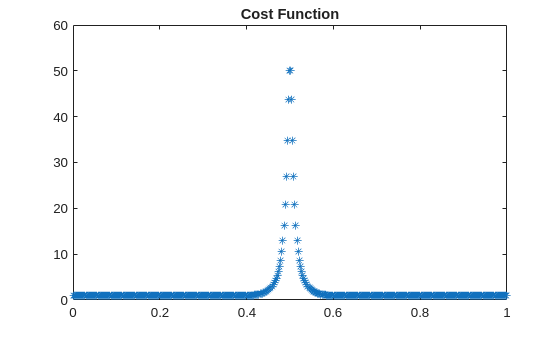

figure(2);
plot(x,c,'*');
title('Cost Function');

## 2. 5th order WENO Fast Sweep Algorithm

Now is the time when i will be implementing the Fast Sweep algorithm. So given below is the eikonal euqation thta i will be solving as my governign equation. And this is just that **Magnitude of gradient of potential is equal to cost function**. So with that, being siad, I have also given below the algorithm in oine dimensional that i have derived from the paper.

The value of eta is taken to be:

The value of initila value of phi is taken to be inifinity and that is equal to

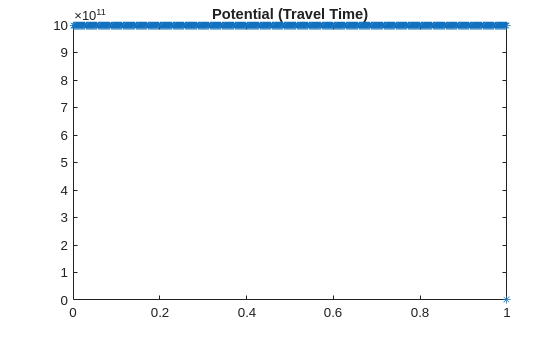

phi = Fast_Sweep_Algorithm(c,N,L);
figure(3);
plot(x,phi,"*");
title('Potential (Travel Time)');


function phi = Fast_Sweep_Algorithm(cost,N,L)

    error_eta = 10^-9;
    eta = 10^-6;
    infinity = 10^12;
    h = L/N;

    %--Intialise the value of phi--%
    phi = infinity*ones(N);
    phi_old = zeros(N);

    % while sum(abs(phi_old - phi)) > error_eta
    for k = 1:1:10
        %--Updating phi values--%
        phi_old = phi;      

        %--Directional Sweep--%
        for sweep = 1:2
            switch sweep
            case 1
                ix = 3:1:N-2;
            case 2
                ix = N-2:-1:3;
            end
            
            %--Boundary Condition--%
            phi(1) = phi(2);
            phi(N) = 0;

            %--Algorithm--%
            for i = ix
                r_back  = (eta + (phi(i) - 2*phi(i-1) + phi(i-2))^2) / (eta + (phi(i+1) - 2*phi(i) + phi(i-1))^2);
                r_front = (eta + (phi(i) - 2*phi(i+1) + phi(i+2))^2) / (eta + (phi(i+1) - 2*phi(i) + phi(i-1))^2);

                w_back  = 1 / (1 + 2*r_back^2);
                w_front = 1 / (1 + 2*r_front^2);

                phi_back    = (1 - w_back) * ((phi(i+1) - phi(i-1))/(2*h)) + w_back * ((3*phi(i) - 4*phi(i-1) + phi(i-2))/(2*h));
                phi_front   = (1 - w_front) * ((phi(i+1) - phi(i-1))/(2*h)) + w_front * ((-3*phi(i) + 4*phi(i+1) - phi(i+2))/(2*h));
            
                phi_min = min(phi(i) - h*phi_back , phi(i) + h*phi_front);

                if abs(phi_min) < cost(i)*h
                    phi(i) = phi_min + cost(i)*h;
                else
                    phi(i) = phi(i);
                end
            end
        end
    end
end